# Test concept: Drop tracking algorithm

clear all 
close all 
clc 


## 1) Load video

vid_file_name = 'SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi'; %<-------- user-defined input!!
vid = VideoReader(vid_file_name); %read video 
totframes = vid.NumFrames %check total num of frames in video

totframes = 1434

## 2) Background generation 

n = 200;    % number of frames to use for background generation  <-------- user-defined input!!
idx = round(linspace(1,totframes,n)); %vector of index of frame number to be extracted

frameMat = []; 

% for loop to create matrix of frames - for generating background image
for i=1:numel(idx)
    frame = read(vid,idx(i)); 
    frameMat = cat(3,frameMat,frame);
end

tic
med_pix = median(frameMat,3); %compute median of each pixel across all frames in matrix
toc

Elapsed time is 1.877273 seconds.


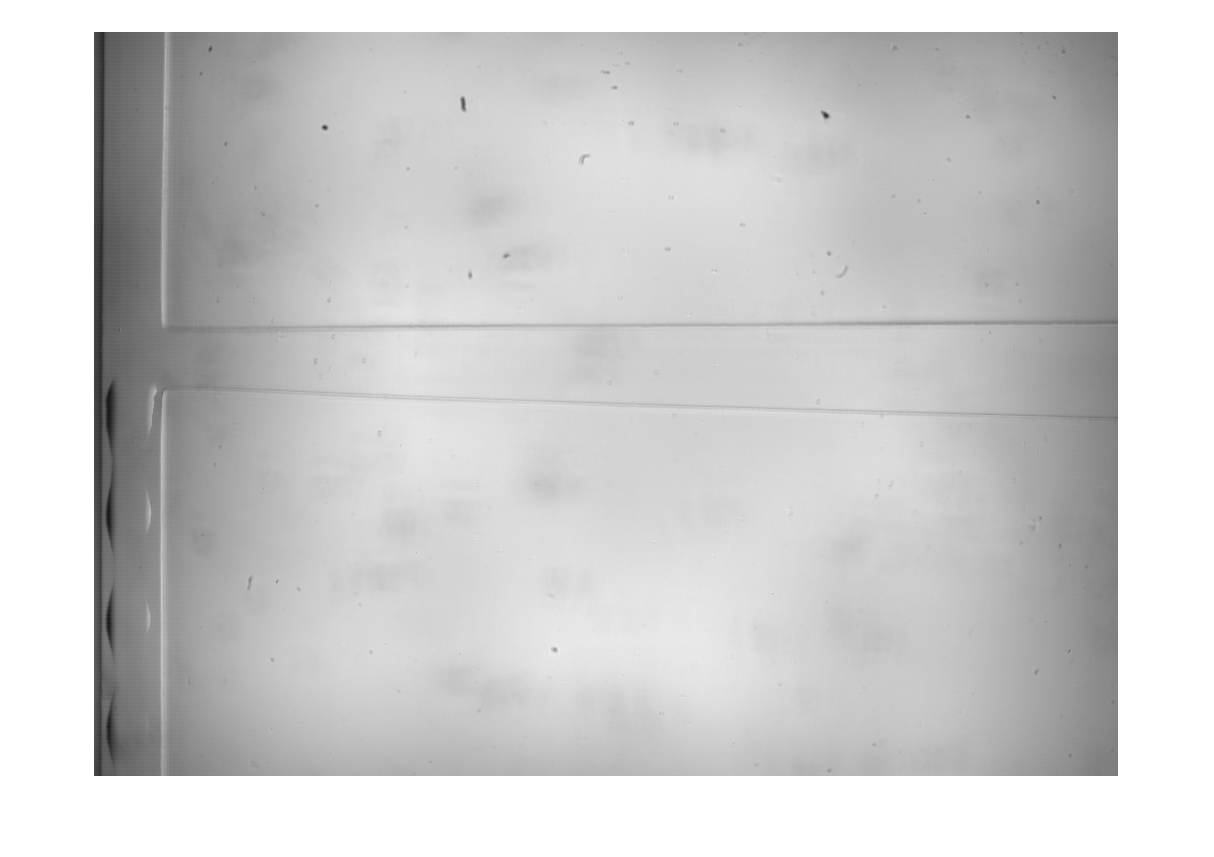


figure; imshow(med_pix);

- test on 1 frame

headers = {'Frame#' 'Drop#' 'Centroid' 'Class'};
varTypes = {'double' 'double' 'double' 'double'};

Ttest = table('Size',[0 4],'VariableTypes',varTypes,'VariableNames',headers)


Ttest =

  0×4 empty table



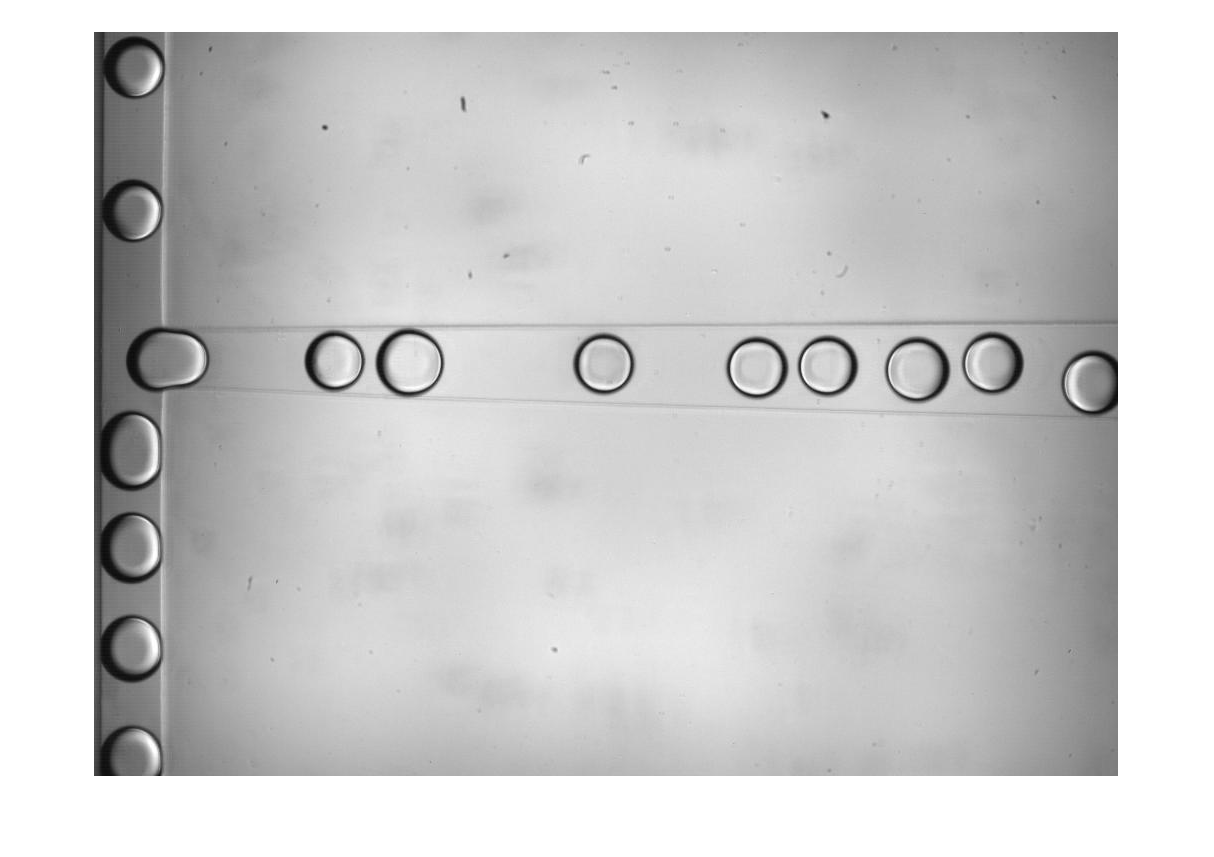


Itest = imread('1.jpg'); 
imshow(Itest)

% background subtraction
subtest = med_pix - Itest; 
% binarise image
bintest = imbinarize(subtest, 0.2); 
% morphological fill
filltest = bwconvhull(bintest,'objects');
% remove noise objects
cfilltest = bwareaopen(filltest, 1800);
% detect area of interest
roitest = regionprops('table',cfilltest);
% remove objects outside of main flow channel
roitest(roitest.Centroid(:,1) < 140, :) = []

roitest = 8×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    3000    241.22    329.67    210.5    298.5       61       62
    3848     316.3    331.31    281.5    296.5       70       70
    3076    510.61    332.53    479.5    301.5       62       62
    3176    663.86    336.39    632.5    304.5       63       64
    3002     734.4    334.61    703.5    303.5       61       62
    3475    824.03     338.4    791.5    304.5       65       67
    3100    899.29    331.81    868.5    300.5       62       63
    3098    998.05    351.55    967.5    318.5       57       66


frameNumtest    = 1111*ones(height(roitest),1);
dropNumtest     =  [1:height(roitest)]';
centroidtest = roitest.Centroid(:,1);
classtest = [1 1 1 1 1 1 1 3]';

datatest = table(frameNumtest, dropNumtest, centroidtest, classtest, 'VariableNames', headers)

datatest = 8×4 table
    Frame#    Drop#    Centroid    Class
    ______    _____    ________    _____

     1111       1       241.22       1  
     1111       2        316.3       1  
     1111       3       510.61       1  
     1111       4       663.86       1  
     1111       5        734.4       1  
     1111       6       824.03       1  
     1111       7       899.29       1  
     1111       8       998.05       3  


Ttest = vertcat(Ttest,datatest)

Ttest = 8×4 table
    Frame#    Drop#    Centroid    Class
    ______    _____    ________    _____

     1111       1       241.22       1  
     1111       2        316.3       1  
     1111       3       510.61       1  
     1111       4       663.86       1  
     1111       5        734.4       1  
     1111       6       824.03       1  
     1111       7       899.29       1  
     1111       8       998.05       3  


- test on multiple frames - need a loop

% access frames
frames_folder = dir('testsample\*.jpg');

% prepare empty table
headers = {'Frame#' 'Drop#' 'Centroid' 'Class'};
varTypes = {'double' 'double' 'double' 'double'};

T = table('Size',[0 4],'VariableTypes',varTypes,'VariableNames',headers)


T =

  0×4 empty table



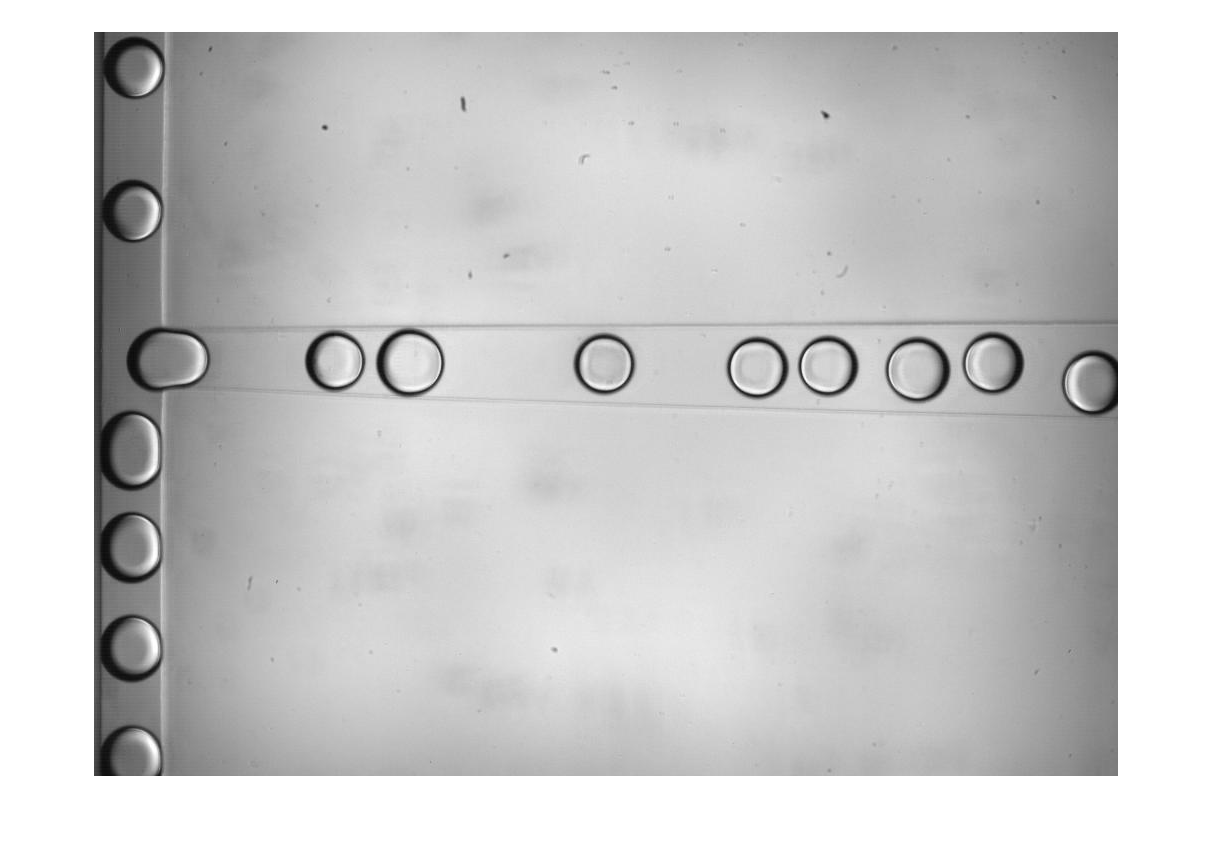

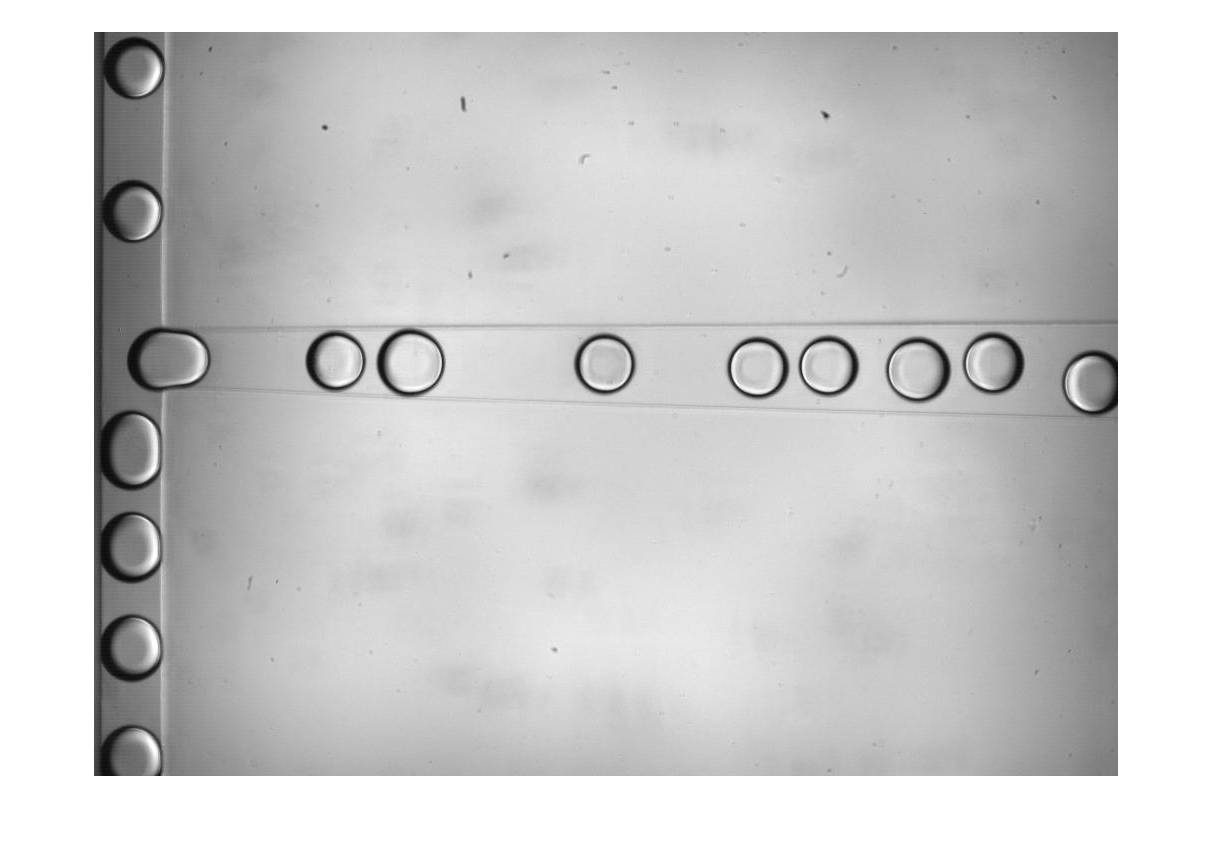

tic
% loop through each frame in folder 
for i = 1:numel(frames_folder)
    
    % get image file name
    filename = fullfile('testsample', sprintf('%d.jpg',i));
    % read image
    img = imread(filename);
    figure; imshow(img)
    
    % background subtraction
    sub = med_pix - img; 
    % binarise image
    bin = imbinarize(sub, 0.2); 
    % morphological fill
    fill = bwconvhull(bin,'objects');
    % remove noise objects
    cfill = bwareaopen(fill, 1800);
    % detect area of interest
    roi = regionprops('table',cfill);
    % remove objects outside of main flow channel
    roi(roi.Centroid(:,1) < 140, :) = [];
    
    % collect data for table
    data = table(i*ones(height(roi),1),...
        [1:height(roi)]',...
        roi.Centroid(:,1),...
        randi(3, height(roi),1), ...
        'VariableNames', headers);
    
    % add data to table
    T = vertcat(T,data);
    
end

toc

Elapsed time is 3.708975 seconds.



% show final data table
T

T = 24×4 table
    Frame#    Drop#    Centroid    Class
    ______    _____    ________    _____

      1         1       241.22       1  
      1         2        316.3       3  
      1         3       510.61       2  
      1         4       663.86       3  
      1         5        734.4       1  
      1         6       824.03       1  
      1         7       899.29       1  
      1         8       998.05       1  
      2         1       241.84       3  
      2         2       316.78       2  
      2         3       511.07       2  
      2         4       664.19       1  
      2         5       734.88       3  
      2         6       824.47       2  
      2         7       899.54       2  
      2         8       998.26       2  


- drop mapping 

% define drop classes fow now - until we have the machine learning
% algorithm

T.Class(1:8) = 1; % assume all drops in frame 1 are single drops 
T.Class(9:16) = [1 1 2 1 1 1 1 1]'; 
T.Class(17:24) = [1 3 3 1 1 1 1 1]';% assume 2nd and 3rd drop coalesced
T

T = 24×4 table
    Frame#    Drop#    Centroid    Class
    ______    _____    ________    _____

      1         1       241.22       1  
      1         2        316.3       1  
      1         3       510.61       1  
      1         4       663.86       1  
      1         5        734.4       1  
      1         6       824.03       1  
      1         7       899.29       1  
      1         8       998.05       1  
      2         1       241.84       1  
      2         2       316.78       1  
      2         3       511.07       2  
      2         4       664.19       1  
      2         5       734.88       1  
      2         6       824.47       1  
      2         7       899.54       1  
      2         8       998.26       1  
